# Part-I 不同编码方式的效用

### `针对以下`5`种编码策略进行编译码:`

- `不编码`

- `仅采用`(8, 3, 4)`码`

- `仅采用`1/2`效率卷积码`

- `先采用`(8, 3, 4)`码方式编码, 后将得到的码流进行`1/2`效率卷积编码`

- `先进行`1/2`效率卷积编码, 后将得到的码流采用`(8, 3, 4)`码方式编码`

`注:使用同一种`2 bits/`符号映射方式通过纯高斯信道（场景一,条件一）,最终的误比特率对比各策略的性能效果`

clear all, close all, clc

## SNR步长为0.1dB效果示例(请检查"Data\PartI_EncodingModes.mat"是否存在)

% snr步长0.1
data = load("Data\PartI_EncodingModes.mat");
snr_dB = data.snr_dB;
BER = data.BER;

% 绘图
figure;
semilogy(snr_dB,BER(1,:), '-', ...
         snr_dB,BER(2,:), '-', ...
         snr_dB,BER(3,:), '-', ...
         snr_dB,BER(4,:), ':', ...
         snr_dB,BER(5,:), '-');
legend( '1: 不编码','2: (8,3,4)码','3: 卷积编码','4: 先(8,3,4)后卷积','5: 先卷积后(8,3,4)', 'Location', 'southwest');
xlabel('复电平信道信噪比（dB）');
ylabel('误比特率');
title('不同编码策略的效果对比')
grid

## 可调参数的完整实现代码

clear all, close all, clc

# *****在此修改参数*****

N = 3000;             % 数据量
snr_low = -10;         % snr最低值(dB)
snr_high = 15;        % snr最高值(dB)
snr_step = 0.5;         % snr步长

### 完整的发编码映射,收解映射译码&绘图

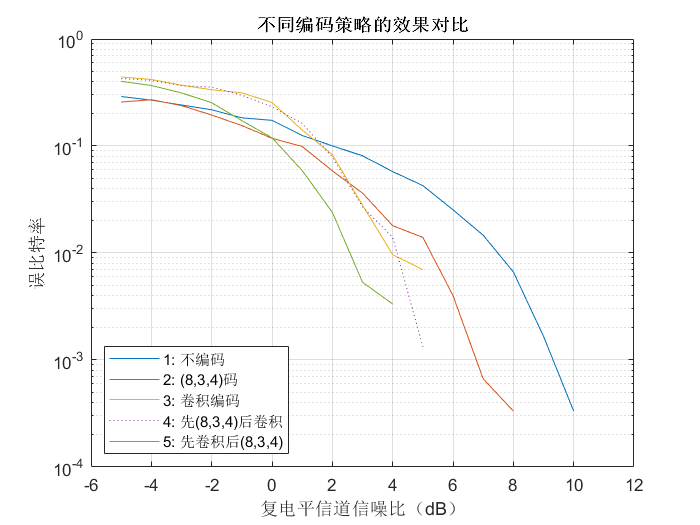

T=5;
x = randi(2, 1, N)-1;   % 传输数据
% 卷积矩阵: 1/2效率
A_2 = [1 1 0 1
     1 1 1 1]';
% 映射矩阵
mbit = 2;               % 映射比特数
Mmap1= [  -sqrt(2)  0;    sqrt(2)  0 ];
Mmap2 = [ -1 -1;    -1  1;    1 -1;    1  1 ];
Mmap3 = sqrt(2)*[cos(pi/8*[-5,-7,5,7,-3,-1,3,1]'),sin(pi/8*[-5,-7,5,7,-3,-1,3,1]')];
% 不添加CRC
crc_code = x;
% 编码: none / conv / (8,3,4) / <combine>
code_none = crc_code;
code_834 = linear_encode(crc_code);
code_conv2 = conv_encode(crc_code, A_2, 1);
code_834_conv2 = conv_encode(code_834, A_2, 1);
code_conv2_834 = linear_encode(code_conv2);

% 映射前的过程与snr无关
snr_dB = snr_low:snr_step:snr_high;     % SNR取值集
BER = repmat(snr_dB*0, [5 1]);          % 误码率记录矩阵: 编码策略数 × SNR取值数
for i=1:length(snr_dB)
    % 映射参数按照snr与mbit进行配置
    snr = 10^(snr_dB(i)/10);
    A = sqrt(snr/2);
    switch mbit
        case 1
            Mmap=A*Mmap1;
        case 2
            Mmap=A*Mmap2;
        otherwise
            Mmap=A*Mmap3;
    end
    % 映射
    u_none = mapping(code_none, 0, mbit, Mmap);
    u_834 = mapping(code_834, 0, mbit, Mmap);
    u_conv2 = mapping(code_conv2, 0, mbit, Mmap);
    u_834_conv2 = mapping(code_834_conv2, 0, mbit, Mmap);
    u_conv2_834 = mapping(code_conv2_834, 0, mbit, Mmap);
    % 信道传输
    v_none = channel(u_none, T, size(u_none, 2));
    v_834 = channel(u_834, T, size(u_834, 2));
    v_conv2 = channel(u_conv2, T, size(u_conv2, 2));
    v_834_conv2 = channel(u_834_conv2, T, size(u_834_conv2, 2));
    v_conv2_834 = channel(u_conv2_834, T, size(u_conv2_834, 2));
    % 解映射
    bit_none = mapping(v_none, 1, mbit, Mmap);
    bit_834 = mapping(v_834, 1, mbit, Mmap);
    bit_conv2 = mapping(v_conv2, 1, mbit, Mmap);
    bit_834_conv2 = mapping(v_834_conv2, 1, mbit, Mmap);
    bit_conv2_834 = mapping(v_conv2_834, 1, mbit, Mmap);
    % 硬判决译码
    h_none = bit_none;                                  % none
    h_834 = linear_decode(bit_834);                     % (8,3,4)
    h_conv2 = viterbi(bit_conv2, A_2, 1, "hard", Mmap); % conv2
    temp = viterbi(bit_834_conv2, A_2, 1, "hard", Mmap);
    h_834_conv2 = linear_decode(temp);                  % (8,3,4)-conv2
    temp = linear_decode(bit_conv2_834);
    h_conv2_834 = viterbi(temp, A_2, 1, "hard", Mmap);  % conv2-(8,3,4)
    % 各自统计误码率并按none, 834, conv2, 834-conv2, conv2-834的顺序存入BER矩阵
    BER(1,i)=sum(abs(h_none-x))/N;
    BER(2,i)=sum(abs(h_834-x))/N;
    BER(3,i)=sum(abs(h_conv2-x))/N;
    BER(4,i)=sum(abs(h_834_conv2-x))/N;
    BER(5,i)=sum(abs(h_conv2_834-x))/N;
end

%save("Data\PartI_EncodingModes_new.mat", "N", "snr_dB", "BER");

% 绘图
figure;
semilogy(snr_dB,BER(1,:), '-', ...
         snr_dB,BER(2,:), '-', ...
         snr_dB,BER(3,:), '-', ...
         snr_dB,BER(4,:), ':', ...
         snr_dB,BER(5,:), '-');
legend( '1: 不编码','2: (8,3,4)码','3: 卷积编码','4: 先(8,3,4)后卷积','5: 先卷积后(8,3,4)', 'Location', 'southwest');
xlabel('复电平信道信噪比（dB）');

ylabel('误比特率');
title('不同编码策略的效果对比')
grid